# UAS Trajectories in a Lane

% Lane Parameters
xd = 1; % The length of the lane
x0 = 0; % The start of the lane
t = linspace(0,1,100);

% UAS parameters
hd_1 = .1;  % The headway separation required by uas 1
hd_2 = .15;  % The headway separation required by uas 2
vg_1 = 1.5;  % The ground speed of uas_1
vg_2 = 4.5;  % The ground speed of uas_2
r_1 = .2;   % The proposed release time of uas 1
r_2 = .5;   % The proposed release time of uas 2

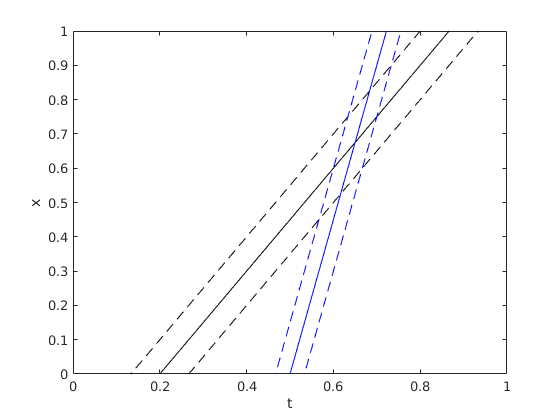

% UAS expected position with respect to time in the lane
x_1 = vg_1*(t-r_1); % The position of uas 1 in the lane
h_1_a = x_1 + hd_1; % The headway distance behind the uas
h_1_b = x_1 - hd_1; % The headway distance in front of the uas
x_2 = vg_2*(t-r_2); % The position of uas 2 in the lane
h_2_a = x_2 + hd_2; % The headway distance behind the uas
h_2_b = x_2 - hd_2; % The headway distance in front of the uas
% plot(t,x_1)

plot(t,x_1,'k-',...
    t,h_1_a,'k--',...
    t,h_1_b,'k--',...
    t,x_2,'b-',...
    t,h_2_a,'b--',...
    t,h_2_b,'b--');
ylim([x0,xd])
xlim([t(1),t(end)])
xlabel('t');
ylabel('x')

d = abs(x_1-x_2);
% d = sqrt((x_1-x_2).^2);
i_1 = find(d<max(hd_1,hd_2));
plot(t,x_1,'k-',...
    t,h_1_a,'k--',...
    t,h_1_b,'k--',...
    t,x_2,'b-',...
    t,h_2_a,'b--',...
    t,h_2_b,'b--');
hold on
plot(t(i_1),x_1(i_1),'r',...
    t(i_1),x_2(i_1),'r');


rx = (vg_2*r_2-vg_1*r_1 + max(hd_2,hd_1))/(vg_2-vg_1)

rx = 0.7000

ry = (-vg_2*r_2+vg_1*r_1 + max(hd_2,hd_1))/(vg_1-vg_2)

ry = 0.6000

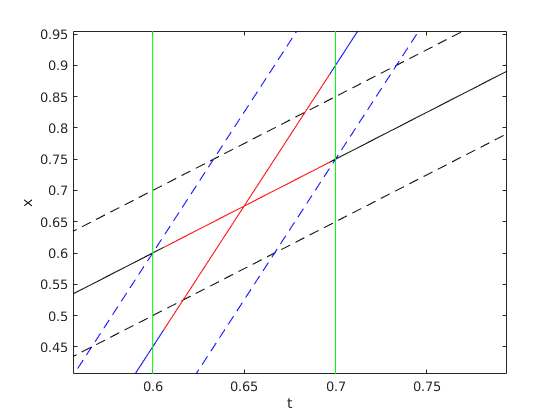

hold on
plot([rx,rx],[0,1],'g',[ry,ry],[0,1],'g')


ylim([x0,xd])
xlim([t(1),t(end)])
xlabel('t');
ylabel('x')

hold off